# **Nonlinear iterative algorithm: KINSOL package benchmark**

This example compares OpenSees Newton and KrylovNewton with the Newton, line-search, modified-Jacobian, and Anderson-accelerated Picard options in KINSOL. The same two-story steel frame is rebuilt before every run. Low post-yield hardening, sustained gravity load, P-Delta columns, an 8% pushover target, and a strong cyclic input make this a deliberately nonlinear case.

**KINSOL** is a solver for nonlinear algebraic systems. See [KINSOL | Computing](https://computing.llnl.gov/projects/sundials/kinsol).

The reported wall time includes only the pushover or transient solution. Model generation and gravity analysis are excluded. Timing results depend on the selected OpenSees system, processor, and MATLAB session; response errors are generally more portable than small timing differences. KINSOL controls the nonlinear iterations. A direct final OpenSees residual check, rather than ConvergenceTest::test(), provides an independent acceptance check; accuracy is also compared against the OpenSees Newton response.

clearvars -except mexDirectory; clc; close all;


if exist('mexDirectory', 'var') && strlength(string(mexDirectory)) > 0
    % Optional development override for testing a newly built MEX binary.
    opsMat = OpenSeesMatlab(mexDir=string(mexDirectory));
else
    opsMat = OpenSeesMatlab();
end


  OpenSeesMatlab v3.8.0.3
  OpenSees MEX Interface for MATLAB
  Copyright (c) 2026, By Yexiang Yan

  Type 'help OpenSeesMatlab' in MATLAB for documentation.
  Documentation also available at
  https://openseesmatlab.readthedocs.io/en/latest/




ops = opsMat.opensees;

solverCases = localSolverCases();
caseNames = string({solverCases.name});
plotStyle = localPlotStyle(numel(solverCases));
% Pushover settings
% 

push.targetRoofDrift = 0.08;
push.numSteps = 160;
push.tolerance = 1.0e-7;
push.maxIterations = 50;

pushover = repmat(localEmptyResult(), numel(solverCases), 1);
for i = 1:numel(solverCases)
    fprintf('Pushover: %s\n', solverCases(i).name);
    pushover(i) = localRunPushover(ops, solverCases(i), push);
end

Pushover: OpenSees Newton
Pushover: OpenSees KrylovNewton
Pushover: KINSOL Newton
Pushover: KINSOL line search
Pushover: KINSOL modified
Pushover: KINSOL Picard + Anderson


pushTable = localPushoverTable(caseNames, pushover);
pushTable

pushTable = 6×12 table
              Solver              Success    CompletedSteps    Time_s     TotalIterations    MeanIterations    MaxIterations    MaxFinalNorm    MaxBaseShearError_kN    RelativeL2Error    ReturnReason    Message
    __________________________    _______    ______________    _______    _______________    ______________    _____________    ____________    ____________________    _______________    ____________    _______

    "OpenSees Newton"              true           160          0.18844          397              2.4813              4           8.7477e-08       

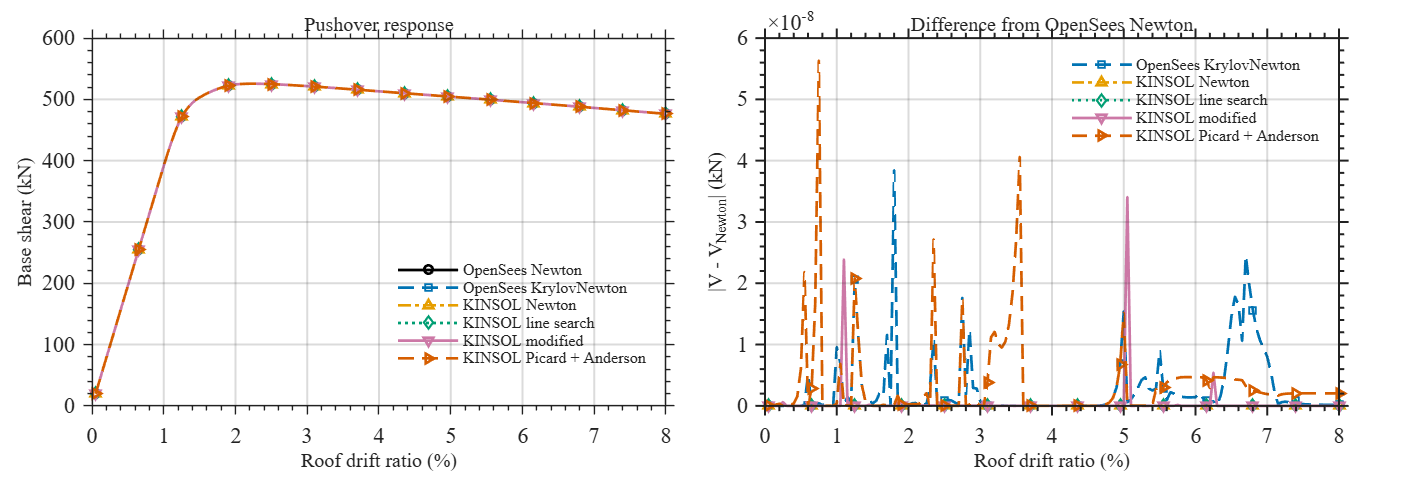

% Pushover response and error
% 

localPublicationFigure('KINSOL steel-frame pushover', [25, 8.5]);
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; hold on; box on; grid on;
for i = 1:numel(solverCases)
    if pushover(i).completedSteps > 0
        plot(100 * pushover(i).x, pushover(i).y, ...
            'Color', plotStyle.colors(i,:), ...
            'LineStyle', plotStyle.lineStyles{i}, ...
            'Marker', plotStyle.markers{i}, ...
            'MarkerIndices', localMarkerIndices(numel(pushover(i).x)), ...
            'MarkerSize', plotStyle.markerSize, ...
            'LineWidth', plotStyle.lineWidth, ...
            'DisplayName', solverCases(i).name);
    end
end
xlabel('Roof drift ratio (%)');
ylabel('Base shear (kN)');
title('Pushover response');
legend('Location', 'best');
localFormatAxes(gca);

nexttile; hold on; box on; grid on;
referencePush = pushover(1);
for i = 2:numel(solverCases)
    [xCommon, errorCurve] = localCurveError(referencePush, pushover(i));
    if ~isempty(xCommon)
        semilogy(100 * xCommon, max(abs(errorCurve), eps), ...
            'Color', plotStyle.colors(i,:), ...
            'LineStyle', plotStyle.lineStyles{i}, ...
            'Marker', plotStyle.markers{i}, ...
            'MarkerIndices', localMarkerIndices(numel(xCommon)), ...
            'MarkerSize', plotStyle.markerSize, ...
            'LineWidth', plotStyle.lineWidth, ...
            'DisplayName', solverCases(i).name);
    end
end
xlabel('Roof drift ratio (%)');
ylabel('|V - V_{Newton}| (kN)');
title('Difference from OpenSees Newton');
legend('Location', 'best');
localFormatAxes(gca);

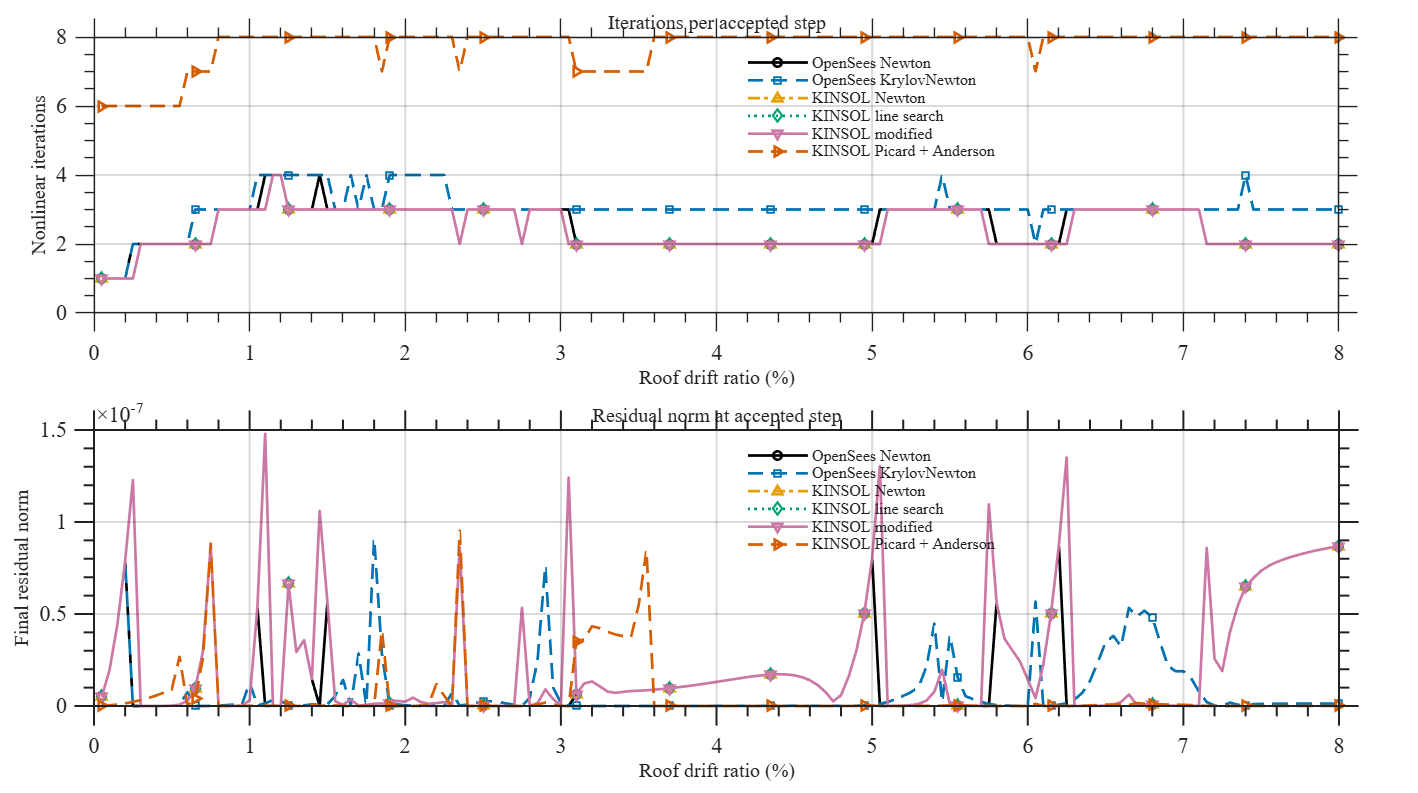

% Pushover convergence history
% 

% OpenSees curves use testIter/testNorms. KINSOL curves use
% nonlinearIterations/finalResidualNorm from algorithm('KINSOL', '-info'). Both describe the
% accepted analysis step, although their iteration counters and stopping rules
% are not mathematically identical.

localPlotConvergence(caseNames, pushover, 'Roof drift ratio (%)', 100, ...
    'Pushover convergence', plotStyle);

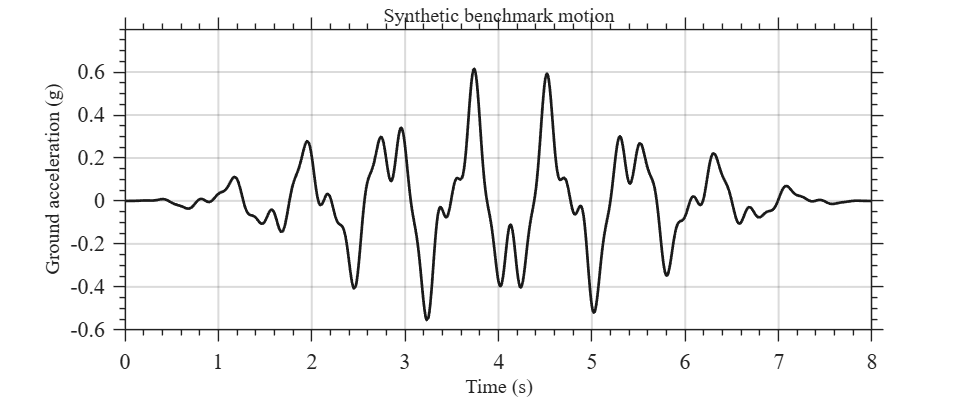

% Ground motion used by every transient run
% 

% A deterministic, modulated broadband record keeps the example
% self-contained. Replace acceleration with a recorded motion when assessing a
% production model.

dynamic.dt = 0.01;
dynamic.duration = 8.0;
dynamic.tolerance = 1.0e-7;
dynamic.maxIterations = 40;
dynamic.dampingRatio = 0.02;
dynamic.time = (0:dynamic.dt:dynamic.duration).';

envelope = sin(pi * dynamic.time / dynamic.duration).^2;
acceleration = envelope .* (...
    0.38 * sin(2*pi*1.15*dynamic.time) + ...
    0.18 * sin(2*pi*2.70*dynamic.time + 0.65) + ...
    0.09 * sin(2*pi*5.10*dynamic.time + 1.20));
dynamic.acceleration = 9.81 * acceleration;

localPublicationFigure('Input acceleration', [17, 7]);
plot(dynamic.time, dynamic.acceleration / 9.81, '-', ...
    'Color', [0.10, 0.10, 0.10], 'LineWidth', plotStyle.lineWidth);
grid on; box on;
xlabel('Time (s)'); ylabel('Ground acceleration (g)');
title('Synthetic benchmark motion');
localFormatAxes(gca);

% Nonlinear transient analysis
% 

transient = repmat(localEmptyResult(), numel(solverCases), 1);
for i = 1:numel(solverCases)
    fprintf('Transient: %s\n', solverCases(i).name);
    transient(i) = localRunTransient(ops, solverCases(i), dynamic);
end

Transient: OpenSees Newton
Transient: OpenSees KrylovNewton
Transient: KINSOL Newton
Transient: KINSOL line search
Transient: KINSOL modified
Transient: KINSOL Picard + Anderson



dynamicTable = localDynamicTable(caseNames, transient);
dynamicTable

dynamicTable = 6×13 table
              Solver              Success    CompletedSteps    Time_s     TotalIterations    MeanIterations    MaxIterations    MaxFinalNorm    PeakRoofDisp_m    MaxDispError_m    RelativeL2Error    ReturnReason    Message
    __________________________    _______    ______________    _______    _______________    ______________    _____________    ____________    ______________    ______________    _______________    ____________    _______

    "OpenSees Newton"              true           800           0.5274         2407  

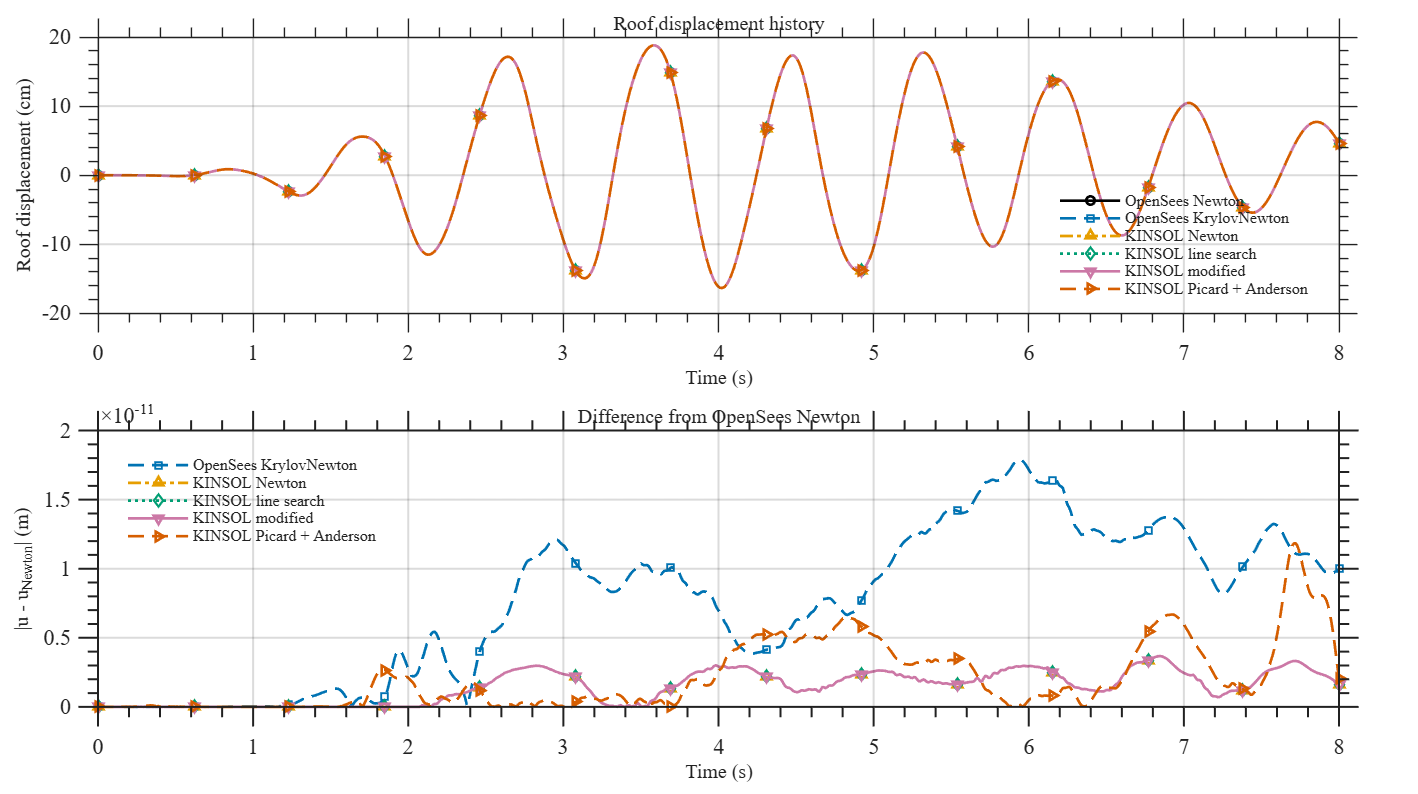

% Dynamic response and error
% 

localPublicationFigure('KINSOL steel-frame transient response', [25, 14]);
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; hold on; box on; grid on;
for i = 1:numel(solverCases)
    if transient(i).completedSteps > 0
        plot(transient(i).x, 100 * transient(i).y, ...
            'Color', plotStyle.colors(i,:), ...
            'LineStyle', plotStyle.lineStyles{i}, ...
            'Marker', plotStyle.markers{i}, ...
            'MarkerIndices', localMarkerIndices(numel(transient(i).x)), ...
            'MarkerSize', plotStyle.markerSize, ...
            'LineWidth', plotStyle.lineWidth, ...
            'DisplayName', solverCases(i).name);
    end
end
xlabel('Time (s)'); ylabel('Roof displacement (cm)');
title('Roof displacement history');
legend('Location', 'best');
localFormatAxes(gca);

nexttile; hold on; box on; grid on;
referenceDynamic = transient(1);
for i = 2:numel(solverCases)
    [timeCommon, errorHistory] = localCurveError(referenceDynamic, transient(i));
    if ~isempty(timeCommon)
        semilogy(timeCommon, max(abs(errorHistory), eps), ...
            'Color', plotStyle.colors(i,:), ...
            'LineStyle', plotStyle.lineStyles{i}, ...
            'Marker', plotStyle.markers{i}, ...
            'MarkerIndices', localMarkerIndices(numel(timeCommon)), ...
            'MarkerSize', plotStyle.markerSize, ...
            'LineWidth', plotStyle.lineWidth, ...
            'DisplayName', solverCases(i).name);
    end
end
xlabel('Time (s)'); ylabel('|u - u_{Newton}| (m)');
title('Difference from OpenSees Newton');
legend('Location', 'best');
localFormatAxes(gca);

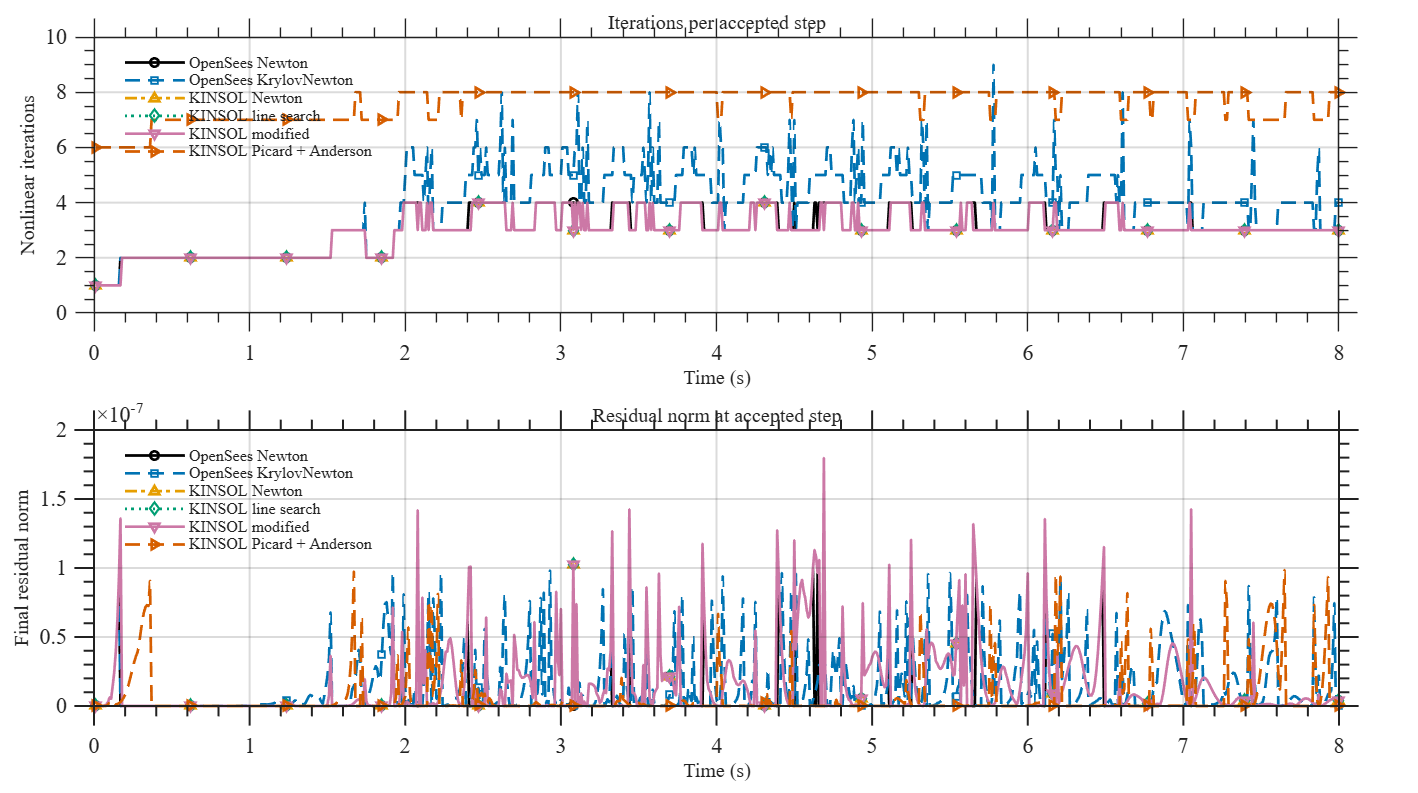

% Transient convergence history
% 

% A residual above fnormTol can still accompany KIN_STEP_LT_STPTOL. The
% response-error plots should therefore be considered together with the norm
% history rather than relying on a single stopping flag.

localPlotConvergence(caseNames, transient, 'Time (s)', 1.0, ...
    'Transient convergence', plotStyle);

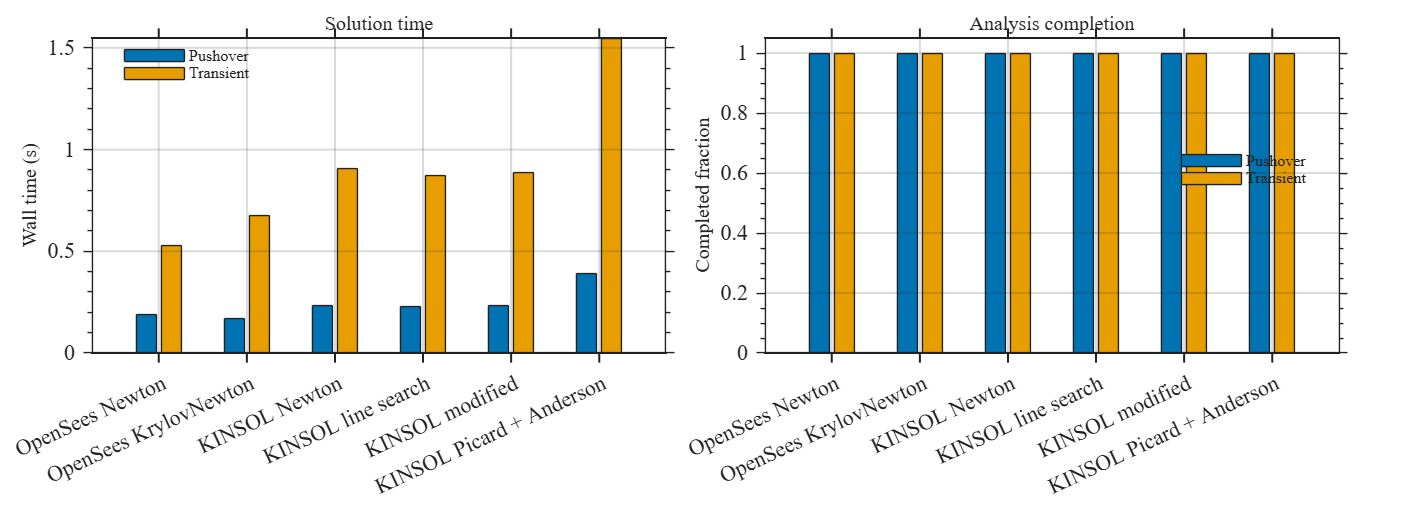

% Runtime and completion summary
% 


localPublicationFigure('KINSOL benchmark summary', [25, 9]);
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile;
b = bar(categorical(caseNames, caseNames), [pushTable.Time_s, dynamicTable.Time_s]);
b(1).FaceColor = [0.00, 0.45, 0.70];
b(2).FaceColor = [0.90, 0.62, 0.00];
grid on; box on;
ylabel('Wall time (s)');
title('Solution time');
legend('Pushover', 'Transient', 'Location', 'best');
xtickangle(25);
localFormatAxes(gca);

nexttile;
b = bar(categorical(caseNames, caseNames), ...
    [pushTable.CompletedSteps ./ push.numSteps, ...
     dynamicTable.CompletedSteps ./ (numel(dynamic.time)-1)]);
b(1).FaceColor = [0.00, 0.45, 0.70];
b(2).FaceColor = [0.90, 0.62, 0.00];
ylim([0, 1.05]); grid on; box on;
ylabel('Completed fraction');
title('Analysis completion');
legend('Pushover', 'Transient', 'Location', 'best');
xtickangle(25);
localFormatAxes(gca);

% Conclusions and discussion
% 

successfulPush = find(pushTable.Success & isfinite(pushTable.Time_s));
successfulDynamic = find(dynamicTable.Success & isfinite(dynamicTable.Time_s));
if ~isempty(successfulPush)
    [~, localIndex] = min(pushTable.Time_s(successfulPush));
    fastestPush = successfulPush(localIndex);
    fprintf('Fastest completed pushover: %s (%.4f s).\n', ...
        pushTable.Solver(fastestPush), pushTable.Time_s(fastestPush));
end

Fastest completed pushover: OpenSees KrylovNewton (0.1703 s).


if ~isempty(successfulDynamic)
    [~, localIndex] = min(dynamicTable.Time_s(successfulDynamic));
    fastestDynamic = successfulDynamic(localIndex);
    fprintf('Fastest completed transient run: %s (%.4f s).\n', ...
        dynamicTable.Solver(fastestDynamic), dynamicTable.Time_s(fastestDynamic));
end

Fastest completed transient run: OpenSees Newton (0.5274 s).


fprintf('Largest completed pushover relative error: %.3e.\n', ...
    max(pushTable.RelativeL2Error(pushTable.Success), [], 'omitnan'));

Largest completed pushover relative error: 1.657e-11.


fprintf('Largest completed transient relative error: %.3e.\n', ...
    max(dynamicTable.RelativeL2Error(dynamicTable.Success), [], 'omitnan'));

Largest completed transient relative error: 1.060e-10.


Newton is used as the numerical reference, not as an exact solution. Curves that agree within the convergence tolerance confirm that the nonlinear backend is solving the same OpenSees equilibrium equations. KrylovNewton and KINSOL modified/Picard variants may reduce tangent factorizations, but they can require more nonlinear iterations when yielding spreads through the frame. 

KINSOL line search is usually the safer KINSOL choice when a full Newton step crosses a sharp stiffness transition. Picard with Anderson is most attractive when factorization dominates cost and the nonlinearity is moderate; failure to complete this benchmark is useful evidence that it is not appropriate for the selected load level. Iteration totals are useful for diagnosing difficult portions of the record, but wall time also depends on how often a tangent is formed and factorized. Consequently, fewer nonlinear iterations do not necessarily imply a faster analysis. OpenSees and KINSOL norms are reported from their native convergence mechanisms and should be compared by trend and tolerance scale, not assumed to be identical internal quantities.

Small timing differences should not be over-interpreted. Repeat the study on the target machine, use the intended sparse system (UmfPack, MUMPS, or CuDSS), and increase the model size before drawing performance conclusions. For snap-through or snap-back behavior, change the integrator or continuation strategy; changing only the nonlinear algorithm does not resolve an unsuitable equilibrium-path parameterization.

ops.wipe();
% Local functions
%

function cases = localSolverCases()
    cases = struct( ...
        'name', { ...
            'OpenSees Newton', ...
            'OpenSees KrylovNewton', ...
            'KINSOL Newton', ...
            'KINSOL line search', ...
            'KINSOL modified', ...
            'KINSOL Picard + Anderson'}, ...
        'kind', { ...
            'newton', 'krylov', 'kinNewton', 'kinLineSearch', ...
            'kinModified', 'kinPicard'});
end

function result = localRunPushover(ops, solverCase, settings)
    result = localEmptyResult();
    try
        model = localBuildFrame(ops);
        localRunGravity(ops);
        ops.loadConst('-time', 0.0);

        ops.timeSeries('Linear', 20);
        ops.pattern('Plain', 20, 20);
        ops.load(model.floor1Left, 50.0, 0.0, 0.0);
        ops.load(model.floor1Right, 50.0, 0.0, 0.0);
        ops.load(model.roofLeft, 100.0, 0.0, 0.0);
        ops.load(model.roofRight, 100.0, 0.0, 0.0);

        ops.wipeAnalysis();
        localConfigureAnalysis(ops, solverCase, settings, 'static');
        increment = settings.targetRoofDrift * model.totalHeight / settings.numSteps;
        ops.integrator('DisplacementControl', model.roofRight, 1, increment);
        ops.analysis('Static');

        roofDrift = nan(settings.numSteps, 1);
        baseShear = nan(settings.numSteps, 1);
        iterations = nan(settings.numSteps, 1);
        residualNorm = nan(settings.numSteps, 1);
        timer = tic;
        for step = 1:settings.numSteps
            result.code = ops.analyze(1);
            if result.code ~= 0
                [result.failureIterations, result.returnReason] = ...
                    localFailureDetails(ops, solverCase.kind, result.code);
                break;
            end
            roofDrift(step) = ops.nodeDisp(model.roofRight, 1) / model.totalHeight;
            ops.reactions();
            baseShear(step) = -(ops.nodeReaction(1, 1) + ops.nodeReaction(2, 1));
            [iterations(step), residualNorm(step)] = ...
                localReadConvergence(ops, solverCase.kind);
            result.completedSteps = step;
        end
        result.elapsed = toc(timer);
        result.x = roofDrift(1:result.completedSteps);
        result.y = baseShear(1:result.completedSteps);
        result.iterations = iterations(1:result.completedSteps);
        result.residualNorm = residualNorm(1:result.completedSteps);
        result.success = result.completedSteps == settings.numSteps;
        if result.success, result.returnReason = "COMPLETED"; end
    catch exception
        result.message = string(exception.message);
        result.elapsed = NaN;
    end
    % ops.wipe();
end

function result = localRunTransient(ops, solverCase, settings)
    result = localEmptyResult();
    try
        model = localBuildFrame(ops);
        localRunGravity(ops);

        eigenvalues = ops.eigen(2);
        omega = sqrt(eigenvalues(:));
        alphaM = 2 * settings.dampingRatio * omega(1) * omega(2) / ...
            (omega(1) + omega(2));
        betaKcomm = 2 * settings.dampingRatio / (omega(1) + omega(2));

        ops.loadConst('-time', 0.0);
        ops.timeSeries('Path', 30, '-dt', settings.dt, ...
            '-values', settings.acceleration(:).', '-factor', 1.0);
        ops.pattern('UniformExcitation', 30, 1, '-accel', 30);
        ops.rayleigh(alphaM, 0.0, 0.0, betaKcomm);

        ops.wipeAnalysis();
        localConfigureAnalysis(ops, solverCase, settings, 'transient');
        ops.integrator('Newmark', 0.5, 0.25);
        ops.analysis('Transient');

        numSteps = numel(settings.time) - 1;
        time = nan(numSteps + 1, 1);
        roof = nan(numSteps + 1, 1);
        iterations = nan(numSteps, 1);
        residualNorm = nan(numSteps, 1);
        time(1) = 0.0;
        roof(1) = ops.nodeDisp(model.roofRight, 1);
        timer = tic;
        for step = 1:numSteps
            result.code = ops.analyze(1, settings.dt);
            if result.code ~= 0
                [result.failureIterations, result.returnReason] = ...
                    localFailureDetails(ops, solverCase.kind, result.code);
                break;
            end
            time(step + 1) = ops.getTime();
            roof(step + 1) = ops.nodeDisp(model.roofRight, 1);
            [iterations(step), residualNorm(step)] = ...
                localReadConvergence(ops, solverCase.kind);
            result.completedSteps = step;
        end
        result.elapsed = toc(timer);
        result.x = time(1:result.completedSteps + 1);
        result.y = roof(1:result.completedSteps + 1);
        result.iterations = iterations(1:result.completedSteps);
        result.residualNorm = residualNorm(1:result.completedSteps);
        result.success = result.completedSteps == numSteps;
        if result.success, result.returnReason = "COMPLETED"; end
    catch exception
        result.message = string(exception.message);
        result.elapsed = NaN;
    end
    ops.wipe();
end

function model = localBuildFrame(ops)
    ops.wipe();
    ops.model('basic', '-ndm', 2, '-ndf', 3);

    bay = 6.0;
    story = 3.5;
    coordinates = [0 0; bay 0; 0 story; bay story; 0 2*story; bay 2*story];
    for tag = 1:size(coordinates, 1)
        ops.node(tag, coordinates(tag, 1), coordinates(tag, 2));
    end
    ops.fix(1, 1, 1, 1);
    ops.fix(2, 1, 1, 1);

    massPerNode = 30.0;
    for tag = 3:6
        ops.mass(tag, massPerNode, 1.0e-9, 1.0e-9);
    end

    steelTag = 1;
    ops.uniaxialMaterial('Steel02', steelTag, 355.0e3, 2.0e8, 0.003, ...
        18.0, 0.925, 0.15);
    localWideFlangeSection(ops, 1, steelTag, 0.34, 0.26, 0.013, 0.022);
    localWideFlangeSection(ops, 2, steelTag, 0.30, 0.22, 0.011, 0.018);

    ops.geomTransf('PDelta', 1);
    ops.geomTransf('Linear', 2);
    ops.beamIntegration('Lobatto', 1, 1, 5);
    ops.beamIntegration('Lobatto', 2, 2, 5);

    ops.element('forceBeamColumn', 1, 1, 3, 1, 1);
    ops.element('forceBeamColumn', 2, 2, 4, 1, 1);
    ops.element('forceBeamColumn', 3, 3, 5, 1, 1);
    ops.element('forceBeamColumn', 4, 4, 6, 1, 1);
    ops.element('forceBeamColumn', 5, 3, 4, 2, 2);
    ops.element('forceBeamColumn', 6, 5, 6, 2, 2);

    ops.timeSeries('Linear', 1);
    ops.pattern('Plain', 1, 1);
    for tag = 3:6
        ops.load(tag, 0.0, -450.0, 0.0);
    end

    model.floor1Left = 3;
    model.floor1Right = 4;
    model.roofLeft = 5;
    model.roofRight = 6;
    model.totalHeight = 2 * story;
end

function localWideFlangeSection(ops, sectionTag, materialTag, d, bf, tw, tf)
    webHalf = 0.5 * (d - 2*tf);
    flangeHalf = 0.5 * bf;
    webHalfWidth = 0.5 * tw;
    ops.section('Fiber', sectionTag);
    ops.patch('rect', materialTag, 12, 2, -webHalf, -webHalfWidth, ...
        webHalf, webHalfWidth);
    ops.patch('rect', materialTag, 2, 12, webHalf, -flangeHalf, ...
        0.5*d, flangeHalf);
    ops.patch('rect', materialTag, 2, 12, -0.5*d, -flangeHalf, ...
        -webHalf, flangeHalf);
end

function localRunGravity(ops)
    ops.constraints('Transformation');
    ops.numberer('RCM');
    ops.system('BandGeneral');
    ops.test('NormUnbalance', 1.0e-8, 40, 0);
    ops.algorithm('Newton');
    ops.integrator('LoadControl', 0.1);
    ops.analysis('Static');
    code = ops.analyze(10);
    if code ~= 0
        error('Gravity analysis failed with code %d.', code);
    end
end

function localConfigureAnalysis(ops, solverCase, settings, analysisType)
    ops.constraints('Transformation');
    ops.numberer('RCM');
    ops.system('BandGeneral');
    ops.test('NormUnbalance', settings.tolerance, settings.maxIterations, 0);

    switch solverCase.kind
        case 'newton'
            ops.algorithm('Newton');
    
        case 'krylov'
            ops.algorithm('KrylovNewton', '-maxDim', 10);
    
        case 'kinNewton'
            ops.call('algorithm', 'KINSOL', ...
                '-method', 'newton', ...
                '-funcNormTol', settings.tolerance, '-collectStats');
    
        case 'kinLineSearch'
            ops.call('algorithm', 'KINSOL', ...
                '-method', 'lineSearch', ...
                '-funcNormTol', settings.tolerance, '-collectStats');
    
        case 'kinModified'
            ops.call('algorithm', 'KINSOL', ...
                '-method', 'modified', ...
                '-funcNormTol', settings.tolerance, '-collectStats');
    
        case 'kinPicard'
            ops.call('algorithm', 'KINSOL', ...
                '-method', 'picard', ...
                '-funcNormTol', settings.tolerance, '-collectStats');
    
        otherwise
            error('Unknown solver case: %s', solverCase.kind);
    end

    if strcmp(analysisType, 'static')
        return;
    end
end

function tableOut = localPushoverTable(names, results)
    reference = results(1);
    count = numel(results);
    time = nan(count, 1);
    completed = zeros(count, 1);
    maxError = nan(count, 1);
    relativeL2 = nan(count, 1);
    success = false(count, 1);
    totalIterations = zeros(count, 1);
    meanIterations = nan(count, 1);
    maxIterations = nan(count, 1);
    maxFinalNorm = nan(count, 1);
    returnReason = strings(count, 1);
    message = strings(count, 1);
    for i = 1:count
        time(i) = results(i).elapsed;
        completed(i) = results(i).completedSteps;
        success(i) = results(i).success;
        [totalIterations(i), meanIterations(i), maxIterations(i), ...
            maxFinalNorm(i)] = localConvergenceSummary(results(i));
        totalIterations(i) = totalIterations(i) + results(i).failureIterations;
        returnReason(i) = results(i).returnReason;
        message(i) = results(i).message;
        [~, difference, referenceValues] = localCurveError(reference, results(i));
        if ~isempty(difference)
            maxError(i) = max(abs(difference));
            relativeL2(i) = norm(difference) / max(norm(referenceValues), eps);
        end
    end
    tableOut = table(names(:), success, completed, time, totalIterations, ...
        meanIterations, maxIterations, maxFinalNorm, maxError, relativeL2, ...
        returnReason, message, ...
        'VariableNames', {'Solver', 'Success', 'CompletedSteps', 'Time_s', ...
        'TotalIterations', 'MeanIterations', 'MaxIterations', 'MaxFinalNorm', ...
        'MaxBaseShearError_kN', 'RelativeL2Error', 'ReturnReason', 'Message'});
end

function tableOut = localDynamicTable(names, results)
    reference = results(1);
    count = numel(results);
    time = nan(count, 1);
    completed = zeros(count, 1);
    peak = nan(count, 1);
    maxError = nan(count, 1);
    relativeL2 = nan(count, 1);
    success = false(count, 1);
    totalIterations = zeros(count, 1);
    meanIterations = nan(count, 1);
    maxIterations = nan(count, 1);
    maxFinalNorm = nan(count, 1);
    returnReason = strings(count, 1);
    message = strings(count, 1);
    for i = 1:count
        time(i) = results(i).elapsed;
        completed(i) = results(i).completedSteps;
        success(i) = results(i).success;
        [totalIterations(i), meanIterations(i), maxIterations(i), ...
            maxFinalNorm(i)] = localConvergenceSummary(results(i));
        totalIterations(i) = totalIterations(i) + results(i).failureIterations;
        returnReason(i) = results(i).returnReason;
        message(i) = results(i).message;
        if ~isempty(results(i).y)
            peak(i) = max(abs(results(i).y));
        end
        [~, difference, referenceValues] = localCurveError(reference, results(i));
        if ~isempty(difference)
            maxError(i) = max(abs(difference));
            relativeL2(i) = norm(difference) / max(norm(referenceValues), eps);
        end
    end
    tableOut = table(names(:), success, completed, time, totalIterations, ...
        meanIterations, maxIterations, maxFinalNorm, peak, maxError, relativeL2, ...
        returnReason, message, ...
        'VariableNames', {'Solver', 'Success', 'CompletedSteps', 'Time_s', ...
        'TotalIterations', 'MeanIterations', 'MaxIterations', 'MaxFinalNorm', ...
        'PeakRoofDisp_m', 'MaxDispError_m', 'RelativeL2Error', ...
        'ReturnReason', 'Message'});
end

function [xCommon, difference, referenceValues] = localCurveError(reference, candidate)
    xCommon = [];
    difference = [];
    referenceValues = [];
    if isempty(reference.x) || isempty(candidate.x)
        return;
    end
    upper = min(reference.x(end), candidate.x(end));
    mask = reference.x <= upper + 10*eps(max(1, abs(upper)));
    xCommon = reference.x(mask);
    referenceValues = reference.y(mask);
    if isempty(xCommon)
        return;
    end
    candidateValues = interp1(candidate.x, candidate.y, xCommon, 'linear');
    valid = isfinite(candidateValues) & isfinite(referenceValues);
    xCommon = xCommon(valid);
    referenceValues = referenceValues(valid);
    difference = candidateValues(valid) - referenceValues;
end

function result = localEmptyResult()
    result = struct('success', false, 'code', -999, 'completedSteps', 0, ...
        'elapsed', NaN, 'x', [], 'y', [], 'iterations', [], ...
        'residualNorm', [], 'failureIterations', 0, ...
        'returnReason', "NOT_RUN", 'message', "");
end

function [iterations, residualNorm] = localReadConvergence(ops, solverKind)
    if startsWith(solverKind, 'kin')
        statistics = ops.call('algorithm', 'KINSOL', '-info');
        iterations = statistics.nonlinearIterations;
        residualNorm = statistics.finalResidualNorm;
        return;
    end

    iterations = ops.testIter();
    norms = ops.testNorms();
    norms = norms(:);
    index = min(max(round(iterations), 1), numel(norms));
    residualNorm = norms(index);
end

function [iterations, reason] = localFailureDetails(ops, solverKind, code)
    iterations = 0;
    reason = "ANALYZE_" + string(code);
    if startsWith(solverKind, 'kin')
        statistics = ops.call('algorithm', 'KINSOL', '-info');
        iterations = statistics.nonlinearIterations;
        reason = string(statistics.returnReason);
    end
end

function [total, average, maximum, maxNorm] = localConvergenceSummary(result)
    validIterations = result.iterations(isfinite(result.iterations));
    validNorms = result.residualNorm(isfinite(result.residualNorm));
    total = sum(validIterations);
    if isempty(validIterations)
        average = NaN;
        maximum = NaN;
    else
        average = mean(validIterations);
        maximum = max(validIterations);
    end
    if isempty(validNorms)
        maxNorm = NaN;
    else
        maxNorm = max(validNorms);
    end
end

function localPlotConvergence(names, results, xLabelText, xScale, figureTitle, style)
    localPublicationFigure(figureTitle, [25, 14]);
    tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

    nexttile; hold on; box on; grid on;
    for i = 1:numel(results)
        x = localConvergenceAbscissa(results(i));
        if ~isempty(x)
            plot(xScale*x, results(i).iterations, ...
                'Color', style.colors(i,:), ...
                'LineStyle', style.lineStyles{i}, ...
                'Marker', style.markers{i}, ...
                'MarkerIndices', localMarkerIndices(numel(x)), ...
                'MarkerSize', style.markerSize, ...
                'LineWidth', style.lineWidth, ...
                'DisplayName', names(i));
        end
    end
    xlabel(xLabelText); ylabel('Nonlinear iterations');
    title('Iterations per accepted step');
    legend('Location', 'best');
    localFormatAxes(gca);

    nexttile; hold on; box on; grid on;
    for i = 1:numel(results)
        x = localConvergenceAbscissa(results(i));
        if ~isempty(x)
            semilogy(xScale*x, max(results(i).residualNorm, realmin), ...
                'Color', style.colors(i,:), ...
                'LineStyle', style.lineStyles{i}, ...
                'Marker', style.markers{i}, ...
                'MarkerIndices', localMarkerIndices(numel(x)), ...
                'MarkerSize', style.markerSize, ...
                'LineWidth', style.lineWidth, 'DisplayName', names(i));
        end
    end
    xlabel(xLabelText); ylabel('Final residual norm');
    title('Residual norm at accepted step');
    legend('Location', 'best');
    localFormatAxes(gca);
end

function x = localConvergenceAbscissa(result)
    if isempty(result.iterations)
        x = [];
    elseif numel(result.x) == numel(result.iterations) + 1
        x = result.x(2:end);
    else
        x = result.x(1:numel(result.iterations));
    end
end

function style = localPlotStyle(numberOfCases)
    % Okabe-Ito palette with black retained for the reference solution.
    palette = [ ...
        0.00, 0.00, 0.00; ...
        0.00, 0.45, 0.70; ...
        0.90, 0.62, 0.00; ...
        0.00, 0.62, 0.45; ...
        0.80, 0.47, 0.65; ...
        0.84, 0.37, 0.00; ...
        0.35, 0.70, 0.90];
    style.colors = palette(1:numberOfCases, :);
    style.lineStyles = {'-', '--', '-.', ':', '-', '--'};
    style.markers = {'o', 's', '^', 'd', 'v', '>'};
    style.lineWidth = 1.35;
    style.markerSize = 4.2;
end

function indices = localMarkerIndices(numberOfPoints)
    if numberOfPoints <= 0
        indices = [];
        return;
    end
    numberOfMarkers = min(14, numberOfPoints);
    indices = unique(round(linspace(1, numberOfPoints, numberOfMarkers)));
end

function figureHandle = localPublicationFigure(name, sizeCm)
    figureHandle = figure('Color', 'w', 'Name', name, ...
        'Units', 'centimeters', 'Position', [2, 2, sizeCm], ...
        'PaperPositionMode', 'auto');
end

function localFormatAxes(axisHandle)
    set(axisHandle, ...
        'FontName', 'Times New Roman', ...
        'FontSize', 11, ...
        'LineWidth', 1, ...
        'TickDir', 'out', ...
        'TickLength', [0.015, 0.015], ...
        'XMinorTick', 'on', ...
        'YMinorTick', 'on', ...
        'GridAlpha', 0.16, ...
        'MinorGridAlpha', 0.08, ...
        'Layer', 'top');
    axisHandle.XLabel.FontSize = 10;
    axisHandle.YLabel.FontSize = 10;
    axisHandle.Title.FontSize = 10;
    axisHandle.Title.FontWeight = 'normal';
    legendHandle = axisHandle.Legend;
    if ~isempty(legendHandle)
        legendHandle.FontName = 'Times New Roman';
        legendHandle.FontSize = 8;
        legendHandle.Box = 'off';
    end
end